#### Maciej Górnik

#### gr 1b, 402325

#### EAIiIB, AiR

# **Analiza liniowego systemu II rzędu na płaszczyźnie fazowej**

## Cel ćwiczenia 

Celem ćwiczenia było zapoznanie się z metodą płaszczyzny fazowej, która jest bardzo wygodnym narzędziem do analizy własności (np. stabilność) zarówno liniowych, jak i nieliniowych systemów dynamicznych II rzędu opisanych w przestrzeni stanu.

## Przebieg ćwiczenia

W simulinku stworzono system dynamiczny w postaci równania stanu

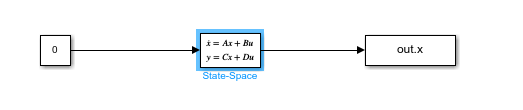

W celu automatycznego uruchomienia tego modelu dla różnych zestawów warunków początkowych wykorzystano skrypt z konspektu.

T = 6; %czas końcowy
[w J] = eig(A); %wektory i wartości własne
figure;hold on; grid on;

%Wyznaczanie zbioru warunków poczakowych obejmujących wszystkie 4 ćwiartki
%płaszczyzny fazowej:
a=0:(pi/10):(2*pi);
X1=[cos(a);sin(a)];

%cykliczne wywoływanie modelu simulinkowego wraz rysowaniem trajektorii:
X2=X1./[max(abs(X1));max(abs(X1))];

M=size(X2,2);
for m=1:M
    x0=X2(:,m);
    out = sim('traj_fazowe',T); %W tym miejscu jest wykonywany model simulinkowy
    x = out.x;
    plot(x(:,1),x(:,2),'k-');
    plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
    title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
    xlabel('x_1');ylabel('x_2');
end;

Wyznaczono trajektorie fazowe dla różnych systemów dynamicznych 2 rzędu opisanych różnymi macierzami stanu.

#### Macierze stanu:

1.Układ stabilny aperiodyczny, dwie różne rzeczywiste wartości własne


$$A=\left\lbrack \begin{array}{cc}
-1 & 0\\
0 & -2
\end{array}\right\rbrack$$


2.Układ stabilny oscylacyjny tłumiony, para wartości własnych zespolonych sprzężonych


$$A=\left\lbrack \begin{array}{cc}
0 & 1\\
-3 & -2
\end{array}\right\rbrack$$


3.Układ oscylacyjny nie tłumiony (granica stabilności), jedna para wartości własnych czysto urojonych


$$A=\left\lbrack \begin{array}{cc}
0 & 1\\
-1 & 0
\end{array}\right\rbrack$$


4.Układ z całkowaniem (granica stabilności), jedna wartość własna rzeczywista, druga równa zero


$$A=\left\lbrack \begin{array}{cc}
0 & 0\\
0 & -1
\end{array}\right\rbrack$$


5.Układ z całkowaniem (granica stabilności), jedna wartość własna rzeczywista, druga równa zero


$$A=\left\lbrack \begin{array}{cc}
0 & 2\\
0 & -1
\end{array}\right\rbrack$$


6.Układ niestabilny, jedna wartość własna dodatnia, druga ujemna (punkt równowagi to punkt „siodłowy”)


$$A=\left\lbrack \begin{array}{cc}
0\ldotp 5 & 0\\
0 & -0\ldotp 5
\end{array}\right\rbrack$$


7.Układ niestabilny, jedna wartość własna dodatnia, druga ujemna (punkt równowagi to punkt „siodłowy”)


$$A=\left\lbrack \begin{array}{cc}
0 & 0\ldotp 1\\
0\ldotp 2 & 0
\end{array}\right\rbrack$$


8.Układ niestabilny, jedna wartość własna rzeczywista, druga równa zero


$$A=\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 1
\end{array}\right\rbrack$$


A = [-1,0;0,-2];
A2 = [0,1;-3,-2];
A3 = [0,1;-1, 0];
A4 = [0,0;0,-1];
A5 = [0,2;0,-1];
A6 = [0.5,0;0,-0.5];
A7 = [0,0.1;0.2,0];
A8 = [0,0;0,1];



### 1.Układ stabilny aperiodyczny, dwie różne rzeczywiste wartości własne

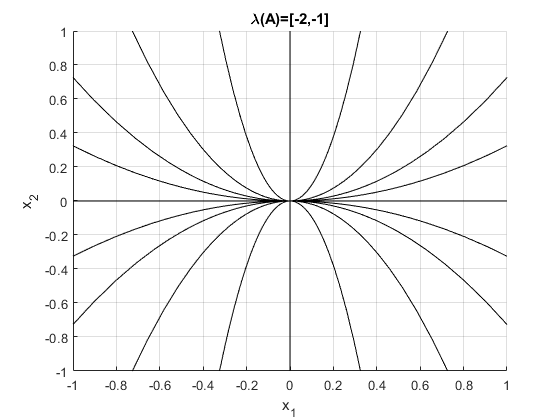

A = [-1,0;0,-2];
T = 6; %czas końcowy
[w J] = eig(A); %wektory i wartości własne
figure;hold on; grid on;

%Wyznaczanie zbioru warunków poczakowych obejmujących wszystkie 4 ćwiartki
%płaszczyzny fazowej:
a=0:(pi/10):(2*pi);
X1=[cos(a);sin(a)];

%cykliczne wywoływanie modelu simulinkowego wraz rysowaniem trajektorii:
X2=X1./[max(abs(X1));max(abs(X1))];

M=size(X2,2);
for m=1:M
    x0=X2(:,m);
    out = sim('traj_fazowe',T); %W tym miejscu jest wykonywany model simulinkowy
    x = out.x;
    plot(x(:,1),x(:,2),'k-');
    plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
    title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
    xlabel('x_1');ylabel('x_2');
end;

### 2.Układ stabilny oscylacyjny tłumiony, para wartości własnych zespolonych sprzężonych

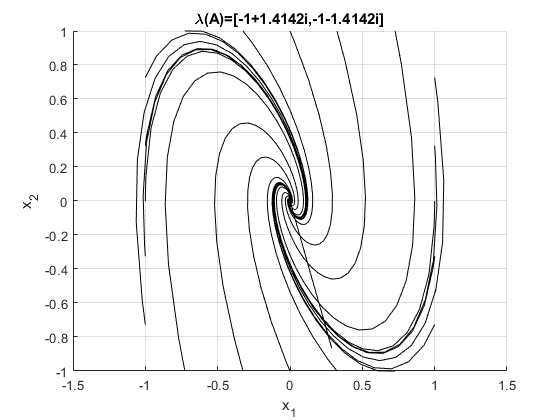

A = A2;
T = 6; %czas końcowy
[w J] = eig(A); %wektory i wartości własne
figure;hold on; grid on;

%Wyznaczanie zbioru warunków poczakowych obejmujących wszystkie 4 ćwiartki
%płaszczyzny fazowej:
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];

%cykliczne wywoływanie modelu simulinkowego wraz rysowaniem trajektorii:
X2=X1./[max(abs(X1));max(abs(X1))];
M=size(X2,2);
for m=1:M
    x0=X2(:,m);
    out = sim('traj_fazowe',T); %W tym miejscu jest wykonywany model simulinkowy
    x = out.x;
    plot(x(:,1),x(:,2),'k-');
    plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
    title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
    xlabel('x_1');ylabel('x_2');
end;

### 3.Układ oscylacyjny nie tłumiony (granica stabilności), jedna para wartości własnych czysto urojonych

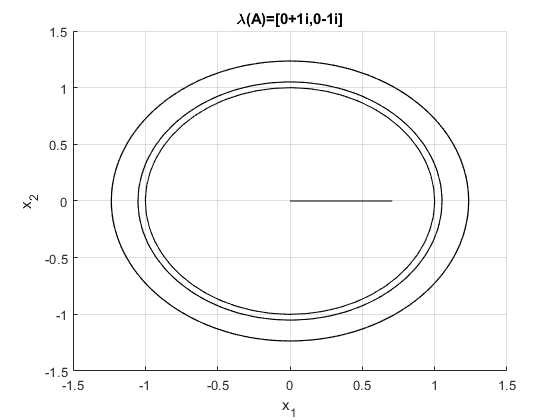

A = A3;
T = 6; %czas końcowy
[w J] = eig(A); %wektory i wartości własne
figure;hold on; grid on;

%Wyznaczanie zbioru warunków poczakowych obejmujących wszystkie 4 ćwiartki
%płaszczyzny fazowej:
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];

%cykliczne wywoływanie modelu simulinkowego wraz rysowaniem trajektorii:
X2=X1./[max(abs(X1));max(abs(X1))];
M=size(X2,2);
for m=1:M
    x0=X2(:,m);
    out = sim('traj_fazowe',T); %W tym miejscu jest wykonywany model simulinkowy
    x = out.x;
    plot(x(:,1),x(:,2),'k-');
    plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
    title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
    xlabel('x_1');ylabel('x_2');
end;

### 4.Układ z całkowaniem (granica stabilności), jedna wartość własna rzeczywista, druga równa zero

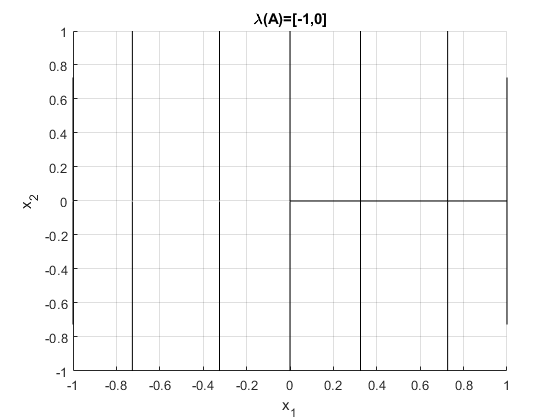

A = A4;
T = 6; %czas końcowy
[w J] = eig(A); %wektory i wartości własne
figure;hold on; grid on;

%Wyznaczanie zbioru warunków poczakowych obejmujących wszystkie 4 ćwiartki
%płaszczyzny fazowej:
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];

%cykliczne wywoływanie modelu simulinkowego wraz rysowaniem trajektorii:
X2=X1./[max(abs(X1));max(abs(X1))];
M=size(X2,2);
for m=1:M
    x0=X2(:,m);
    out = sim('traj_fazowe',T); %W tym miejscu jest wykonywany model simulinkowy
    x = out.x;
    plot(x(:,1),x(:,2),'k-');
    plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
    title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
    xlabel('x_1');ylabel('x_2');
end;

### 5.Układ z całkowaniem (granica stabilności), jedna wartość własna rzeczywista, druga równa zero

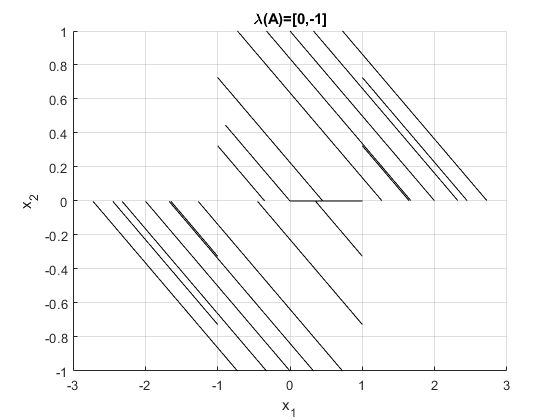

A = A5;
T = 6; %czas końcowy
[w J] = eig(A); %wektory i wartości własne
figure;hold on; grid on;

%Wyznaczanie zbioru warunków poczakowych obejmujących wszystkie 4 ćwiartki
%płaszczyzny fazowej:
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];

%cykliczne wywoływanie modelu simulinkowego wraz rysowaniem trajektorii:
X2=X1./[max(abs(X1));max(abs(X1))];
M=size(X2,2);
for m=1:M
    x0=X2(:,m);
    out = sim('traj_fazowe',T); %W tym miejscu jest wykonywany model simulinkowy
    x = out.x;
    plot(x(:,1),x(:,2),'k-');
    plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
    title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
    xlabel('x_1');ylabel('x_2');
end;

### 6.Układ niestabilny, jedna wartość własna dodatnia, druga ujemna (punkt równowagi to punkt „siodłowy”)

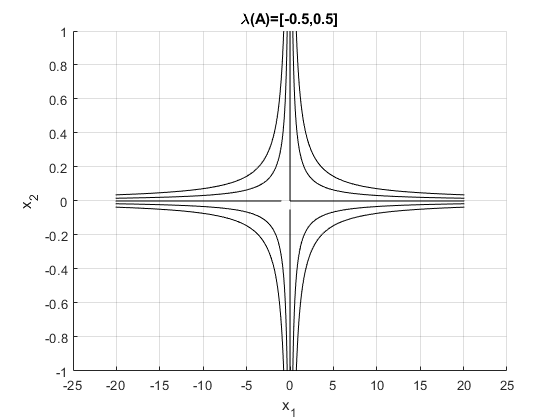

A = A6;
T = 6; %czas końcowy
[w J] = eig(A); %wektory i wartości własne
figure;hold on; grid on;

%Wyznaczanie zbioru warunków poczakowych obejmujących wszystkie 4 ćwiartki
%płaszczyzny fazowej:
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];

%cykliczne wywoływanie modelu simulinkowego wraz rysowaniem trajektorii:
X2=X1./[max(abs(X1));max(abs(X1))];
M=size(X2,2);
for m=1:M
    x0=X2(:,m);
    out = sim('traj_fazowe',T); %W tym miejscu jest wykonywany model simulinkowy
    x = out.x;
    plot(x(:,1),x(:,2),'k-');
    plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
    title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
    xlabel('x_1');ylabel('x_2');
end;

### 7.Układ niestabilny, jedna wartość własna dodatnia, druga ujemna (punkt równowagi to punkt „siodłowy”)

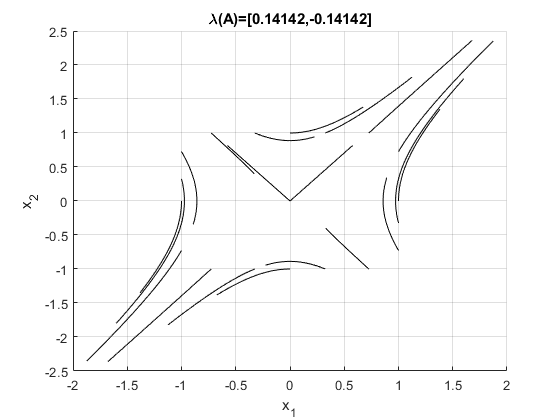

A = A7;
T = 6; %czas końcowy
[w J] = eig(A); %wektory i wartości własne
figure;hold on; grid on;

%Wyznaczanie zbioru warunków poczakowych obejmujących wszystkie 4 ćwiartki
%płaszczyzny fazowej:
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];

%cykliczne wywoływanie modelu simulinkowego wraz rysowaniem trajektorii:
X2=X1./[max(abs(X1));max(abs(X1))];
M=size(X2,2);
for m=1:M
    x0=X2(:,m);
    out = sim('traj_fazowe',T); %W tym miejscu jest wykonywany model simulinkowy
    x = out.x;
    plot(x(:,1),x(:,2),'k-');
    plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
    title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
    xlabel('x_1');ylabel('x_2');
end;

### 8.Układ niestabilny, jedna wartość własna rzeczywista, druga równa zero

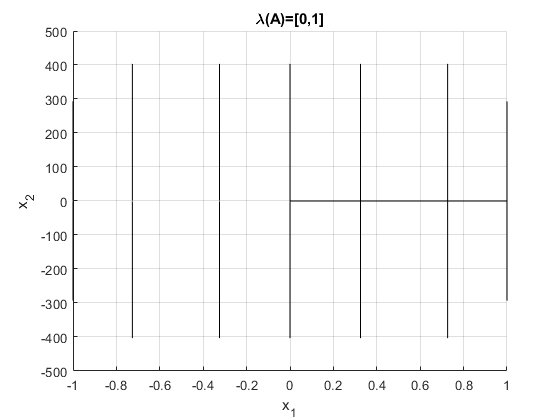

A = A8;
T = 6; %czas końcowy
[w J] = eig(A); %wektory i wartości własne
figure;hold on; grid on;

%Wyznaczanie zbioru warunków poczakowych obejmujących wszystkie 4 ćwiartki
%płaszczyzny fazowej:
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];

%cykliczne wywoływanie modelu simulinkowego wraz rysowaniem trajektorii:
X2=X1./[max(abs(X1));max(abs(X1))];
M=size(X2,2);
for m=1:M
    x0=X2(:,m);
    out = sim('traj_fazowe',T); %W tym miejscu jest wykonywany model simulinkowy
    x = out.x;
    plot(x(:,1),x(:,2),'k-');
    plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
    title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
    xlabel('x_1');ylabel('x_2');
end;